## TOPIC 22: Calculus in MATLAB

ENGR105, 11/12/20

#### Practice problem: diagnosing sickle cell disease

Sickle cell disease is an inherited red blood cell disorder that affects millions of people worldwide and approximately 1 in 3,000 Americans. Normally, red bloods cells are round and flexible: these can easily move through one’s blood vessels. In sickle cell disease, however, red bloods are shaped like “sickles” and are rigid: these diseased cells can slow or block blood flow and oxygen to parts of the body, leading to pain, anemia, a compromised immune system, and other complications. 

Sickle cell disease is caused by a *point mutation* in the gene for hemoglobin, the iron-rich compound that gives blood its red color and enables *red blood cells* to carry oxygen from your lungs to the rest of your body. A point mutation is when *one letter* of a nucleotide sequence ***differs from what is found in a “normal” or healthy sequence***. In this problem, we will consider the *mRNA sequence* of the hemoglobin gene. Recall from lecture that an **mRNA sequence is *just* a sequence of letters (text)**, where each position could be one of four potential letters: **A, U, C, or G**. Each letter corresponds to a different nucleotide, which in turn corresponds to a chemical structure in the mRNA molecule. This sequence of letters represents information about *how* the corresponding protein will be constructed.

Consider the **first 24 nucleotides of the mRNA sequence for the hemoglobin gene**, shown below. *Normally*, the 20th nucleotide is an “**A**,” corresponding to the adenine nucleotide:

AUGGUGCACCUGACUCCUG**A**GGAG

*In a person carrying the sickle cell trait* (and therefore at risk for either having the disease or passing it on to their children), the 20th nucleotide is often instead a “**U**,”, corresponding to the uracil nucleotide:

AUGGUGCACCUGACUCCUG**U**GGAG

**Question**. Produce a script that loads the data and evaluates how well the test works.

% Step 1: Read data from text file. We will use readcell 
patientData = readcell('patientData.txt');

% Step 2: Prepare and preallocate necessary vectors
trueResult = zeros(size(patientData,1),1);  % Blood test result
diagResult = zeros(size(patientData,1),1);  % Diagnostic

% Step 3: Loop through each row (data point / patient) of the collected data
for k = 1:size(patientData,1)
    
    % Evaluate if patient has sickle cell disease based on sequence. Will
    % return 1 if they have sickle cell, 0 if they do not
    trueResult(k) = patientData{k,1}(20) == 'U';
    
    % Evaluate what the diagnostic predicts. Will return 1 if diagnostic
    % indicates sickle cell disease, 0 if it does not.
    diagResult(k) = strcmp(patientData{k,2},'sicklecell');
    
end

% Determine "accuracy" of diagnostic result
% accuracy1: simply finds proportion of predicted true relative to absolute
% true
accuracy1 = sum(diagResult(trueResult == 1))/length(trueResult(trueResult == 1))

accuracy1 = 0.7302

% accuracy2 (better): determines the proportion of test results that the
% diagnostic accurately classified as having sickle cell or not
accuracy2 = sum(trueResult == diagResult) / length(trueResult)

accuracy2 = 0.8759

**A simpler solution**. A 3 line solution can be created using `cellfun`, which applies any specified function to each entry in a specified cell.

- *First input*: function handle

- *Second input*: cell array

% Determine patients that have the disease
trueResult = cellfun(@(y) y(20) == 'U', patientData(:,1));

% Result of diagnostic
diagResult = cellfun(@(x) strcmp(x,'sicklecell'),patientData(:,2));

% Determine accuracy, as above
accuracy1 = sum(diagResult(trueResult == 1))/length(trueResult(trueResult == 1))

accuracy1 = 0.7302

accuracy2 = sum(trueResult == diagResult) / length(trueResult)

accuracy2 = 0.8759

**Takeaway**: always remember to consider vectorization. We've shown that this typically produces more efficient solutions.

### Calculus in MATLAB

MATLAB can be used to tackle calculus problems (integration, differentiation, numerical evaluation of ordinary differential equations)

#### 1-D Differentation

Many problems in engineering revolve around answering questions related to changes:

- What is the tendency of a function at some point?

- What is the slope of a surface or the normal to a surface?

- What is the incremental value of a cost function?

These inquiries may be answered using differentiation – numeric/discrete differentiation may be achieved using `diff()`

% Vector
v = [1,5,15,50,100,200]

v =      1     5    15    50   100   200


% Numeric derivative
dv = diff(v)

dv =      4    10    35    50   100


**Note**: `dv` contains 1 fewer element than `v` because it calculates the *difference* between entries.

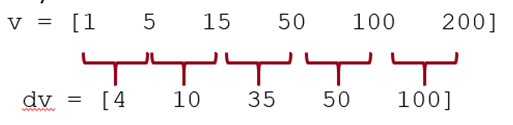

#### Example: Usain Bolt and the 100 m 

In the 2009 World Championships in Athletics, Usain Bolt ran a record 9.58s 100 meter sprint. The positional information for this run is contained in the file `L23_UB_data.xlsx`. Compute Usain Bolt's **velocity** and **acceleration** during this sprint. 

**Side note**: note the file format. Microsoft Excel files can be loaded using `importdata()`. However, a simpler function for this specific file type is `xlsread.`

% Load the data from the excel file
[data,headers] = xlsread('L23_UB_data.xlsx');

The time and position data for this event can be read into MATLAB from a excel file and differentiated to obtain velocity and acceleration. Specifically we need to calculate:

- velocity

            
$$v=\frac{\Delta x}{\Delta t}$$


- acceleration

            
$$a=\frac{\Delta v}{\Delta t}$$


% 1) Place the data in time and position vectors
t = data(:,1);
pos = data(:,2);

% 2) Calculate the velocity and acceleration as a 
% function of time
v = diff(pos)./diff(t);
a = diff(v)./diff(t(2:end));

Having calculated each parameter, we can plot. Note the following shows how you can create multiple axes in a single figure **without** using `subplot`.

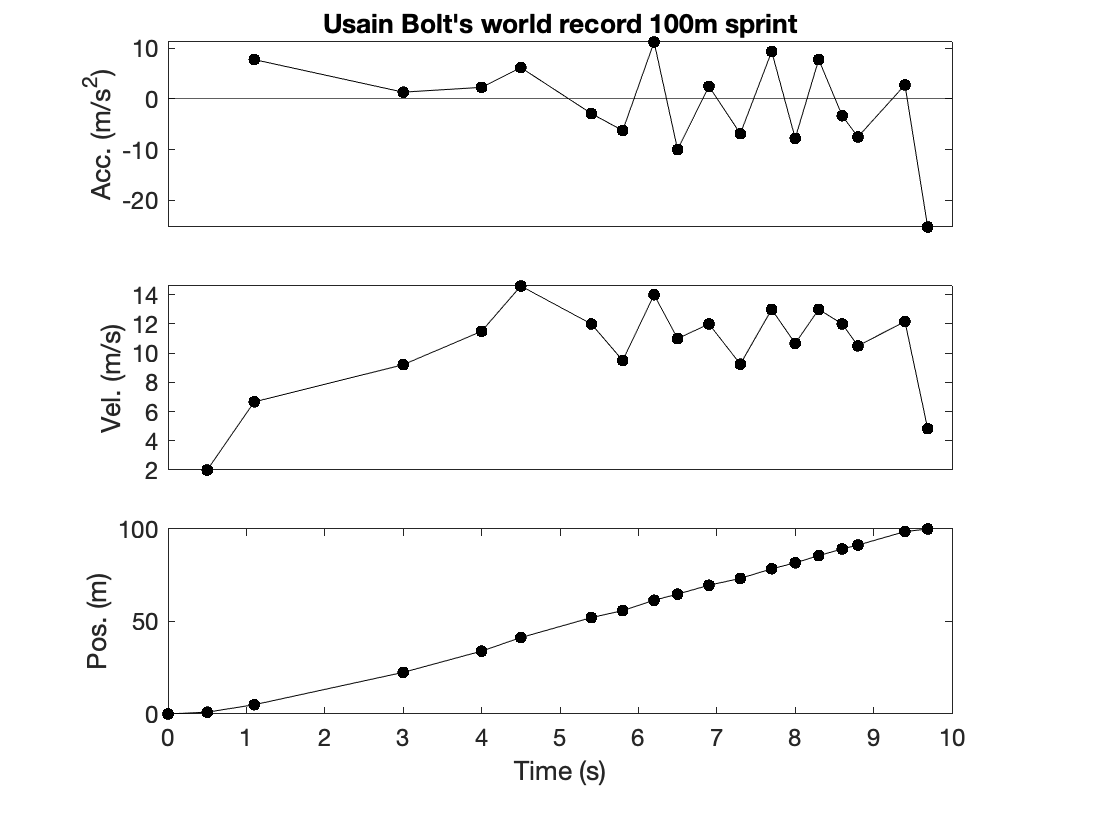

close all
% Produce a plot depicting all results
fs = 12;    % Font size
ms = 16;    % Marker size

% First plot: position vs. time
g1 = axes;
g1.Position = [0.15,0.15,0.7,0.22];
plot(t,pos,'k.-','MarkerSize',ms);
xLim = xlim;
xlabel('Time (s)')
ylabel('Pos. (m)')
g1.FontSize = fs;

% Second plot: velocity vs. time
g2 = axes;
g2.Position = [0.15,0.44,0.7,0.22];
plot(t(2:end),v,'k.-','MarkerSize',ms);
ylabel('Vel. (m/s)')
axis tight
xlim(xLim)
g2.XTick = [];
g2.FontSize = fs;

% Third plot: acceleration vs. time
g3 = axes;
g3.Position = [0.15,0.73,0.7,0.22];
plot(t(3:end),a,'k.-','MarkerSize',ms);
hold on
plot(xLim,[0 0],'k-')
hold off
set(gca,'FontSize',fs)
ylabel('Acc. (m/s^2)')
axis tight
xlim(xLim)
g3.XTick = [];
g3.FontSize = fs;
title('Usain Bolt''s world record 100m sprint')

**Note**: if you use `diff` on a matrix, be sure to specify a dimension. You can also specify an "order" of the difference.

% Declare 2-D array
A = [4,5,6;3,2,1]

A =      4     5     6
     3     2     1


% Difference over rows
diff(A,1,1)

ans =     -1    -3    -5


% Difference over columns
diff(A,1,2)

ans =      1     1
    -1    -1


#### Visualizing and creating multi-dimensional derivatives

"Vector fields" (and 3D data) may be represented using `meshgrid`. `meshgrid` creates matrices of numbers that have as many columns as `length(x)` and as many rows as `length(y)` with `x `repeated along rows and `y` repeated along columns `X` and `Y` represent the `x` and `y` values at each index.

% X values
x = -3:0.5:3;
% Y values
y = -2:0.5:2;
% Create meshgrid
[X,Y] = meshgrid(x,y)

X =    -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000
   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.500

Y =    -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.500

**Note** the definitions of X and Y, above. X corresponds to rows, Y corresponds to columns.

#### Visualizing velocity fields: `quiver` plots

Using data in the above format, you can assign **x and y components of velocity**. Note that the velocity component in a given index location corresponds to the X and Y positional entries in the corresponding indices of X and Y.

% Specify X component of velocity
VX = Y/max(Y,[],'all');

VX =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500
         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500    0.75

% Specify Y component of velocity
VY = -X/max(X,[],'all');

VY =     1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.1667   -0.3333   -0.5000   -0.6667   -0.8333   -1.0000
    1.0000    0.8333    0.6667    0.5000    0.3333    0.1667         0   -0.16

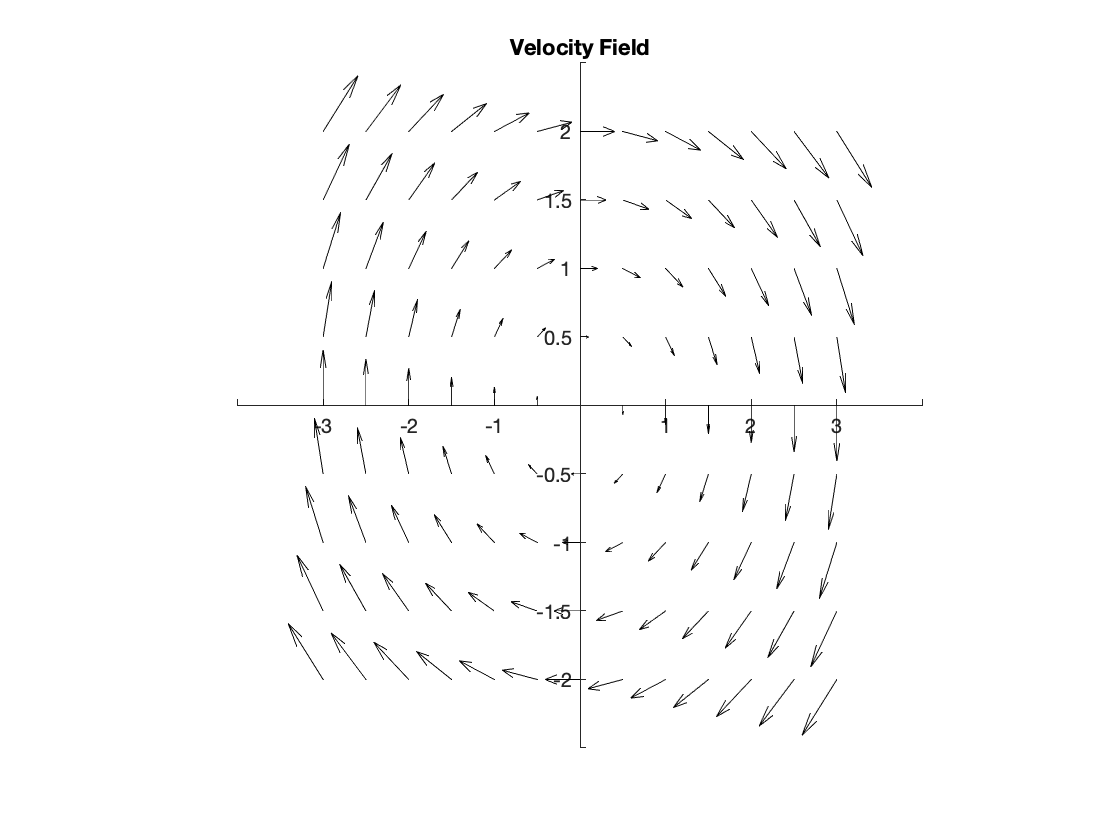

close all
% Visualize the velocity profile
q = quiver(X,Y,VX,VY);
q.Color = 'k';
set(gca,'YAxisLocation','Origin')
set(gca,'XAxisLocation','Origin')
set(gca,'Box','off')
axis square
title('Velocity Field')

#### Visualizing velocity fields: `surface` plots

An alternative, `surface `produces a 3D shaded surface of a matrix or surface with a top down view. 

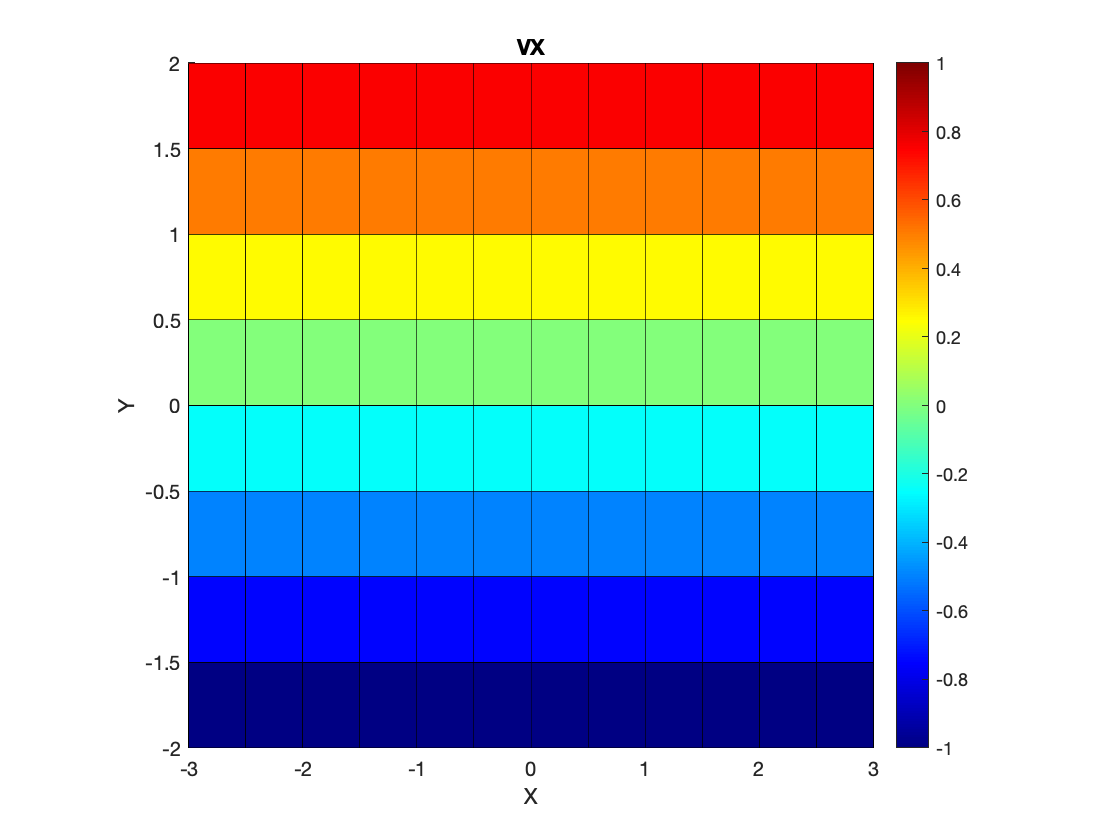

close all

% Plot the X component of the velocity
figure
surface(X,Y,VX)
axis square
title('VX')
xlabel('X')
ylabel('Y')
colorbar
colormap('jet')

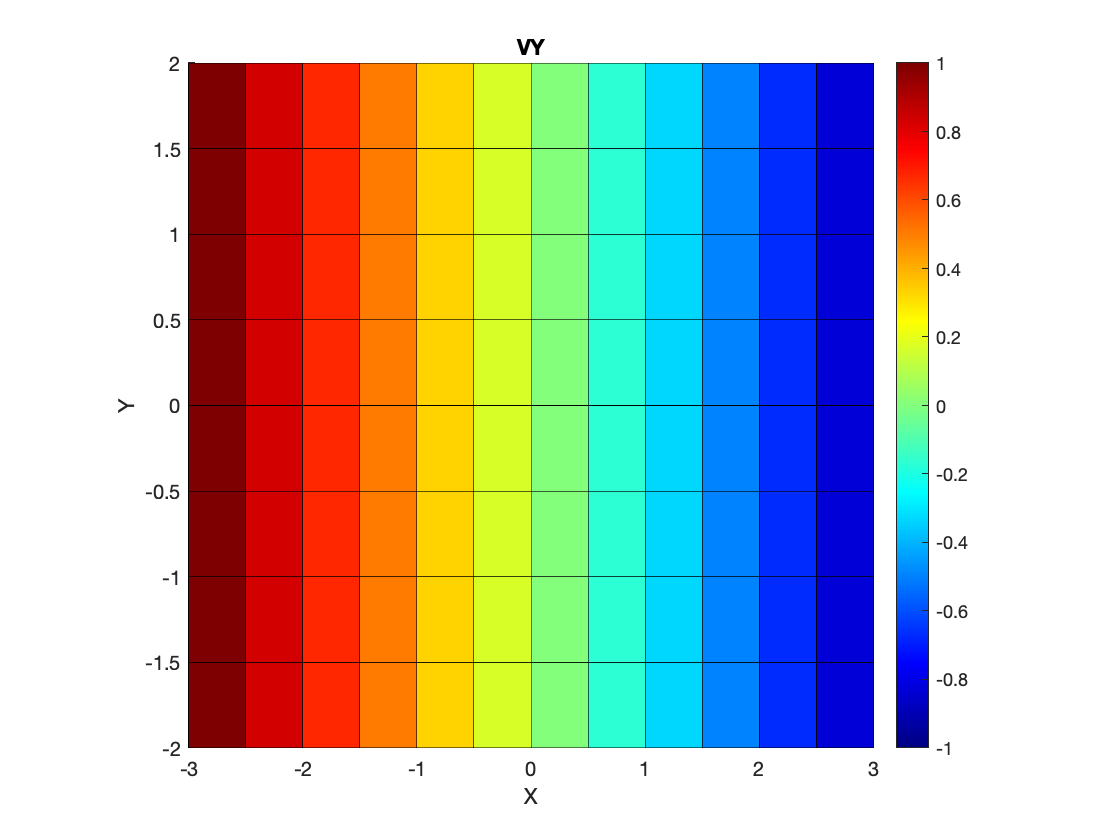


% Plot the Y component of the velocity
figure
surface(X,Y,VY)
axis square
title('VY')
xlabel('X')
ylabel('Y')
colorbar
colormap('jet')

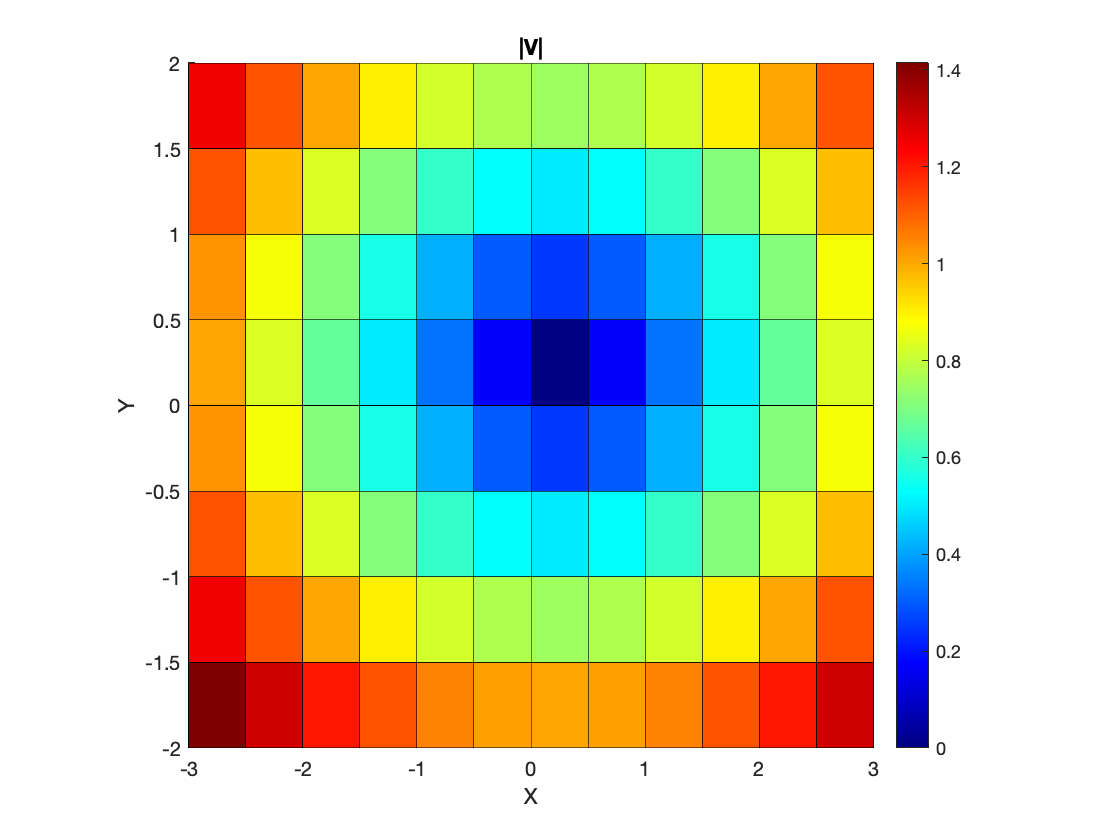


% Plot the magnitude of the velocity
figure
surface(X,Y,sqrt(VY.^2+VX.^2))
axis square
title('|V|')
xlabel('X')
ylabel('Y')
colorbar;
colormap('jet')

**Note**: The above code adds colorbars using the `colorbar` function. The purpose of this is serve as a "color scale."

#### Multi-dimensional differentiatial calculus

In addition to 1-D differentiation, MATLAB can handle multivariable and vector calculus derivatives.

- curl, ∇⨯*F*

- gradient, ∇*F*

- divergence, ∇⋅*F*

Where ∇ = nabla = del operator = $\frac{\partial }{\partial x}\hat{i} +\frac{\partial }{\partial y}\hat{j} +\frac{\partial }{\partial z}\hat{k}$

**Curl. **The curl of a vector is the cross product of the del operator and the vector and can be invoked using the `curl` function in MATLAB. **Note that the curl of a vector returns a vector.**

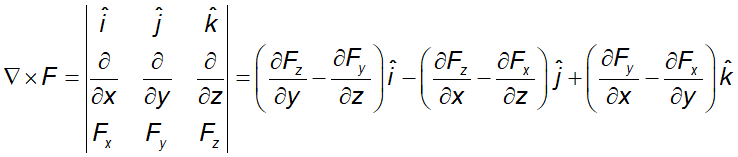

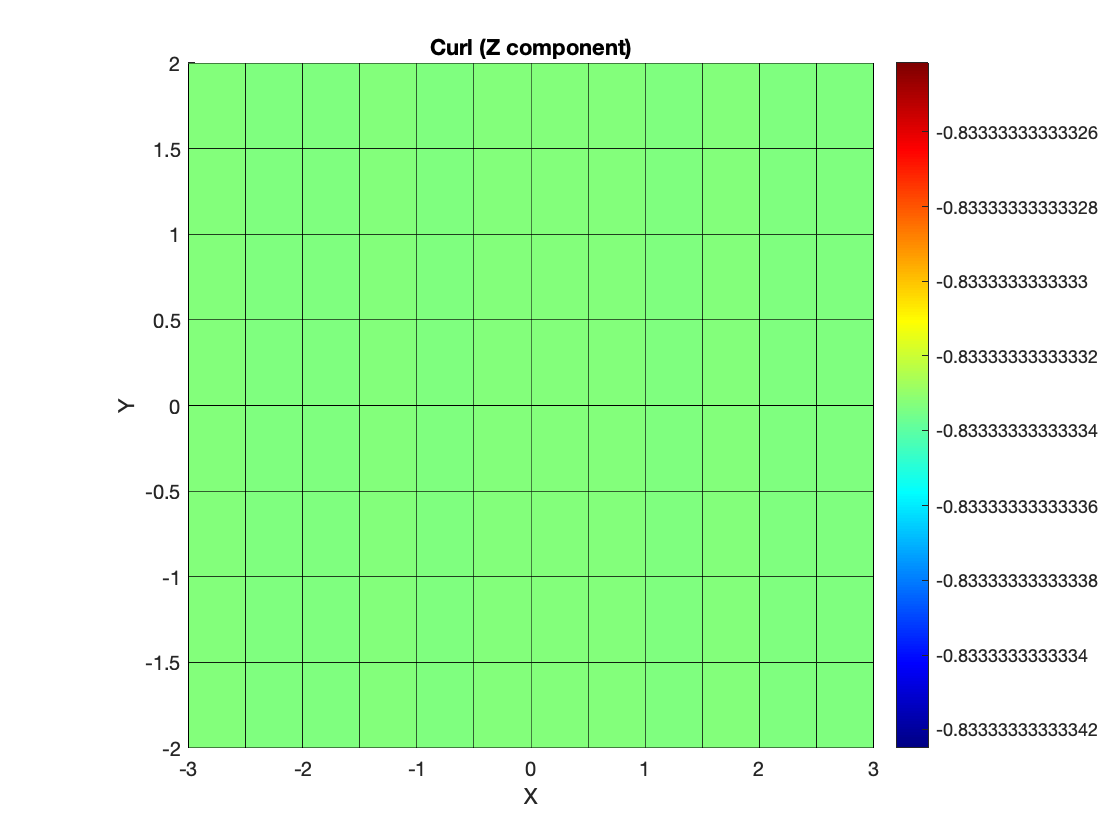

close all
% Compute the curl and angular velocity of the above vector field
[CURLZ, CAV]= curl(X,Y,VX,VY);

% Plot the X component of the velocity
surface(X,Y,CURLZ)
axis square
title('Curl (Z component)')
xlabel('X')
ylabel('Y')
colorbar
colormap('jet')

**In physical systems**, the curl can be thought of as the circulation around an infinitesimal point - the direction of the vector describes the direction of rotation via the right hand rule. 

**In this example**: the entire field is rotating around one point. Thus the curl (and angular velocity) is the same everywhere.

**Gradient**. The gradient of a function is the result of passing a function through the del operator and may invoked using the `gradient `function in MATLAB. **Note that the gradient of a vector returns a vector.**


$$\nabla F=\frac{\partial F}{\partial x}\hat{i} +\frac{\partial F}{\partial y}\hat{j} +\frac{\partial F}{\partial z}\hat{k}$$


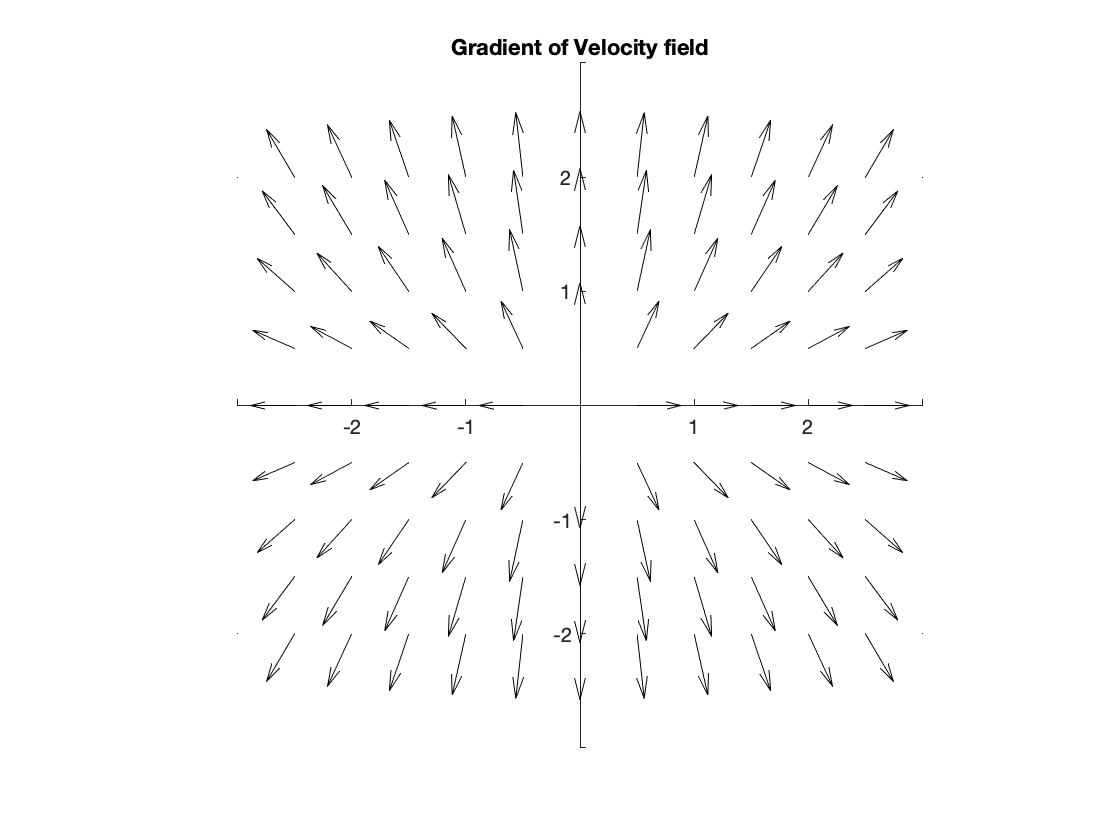

close all
% Compute the curl and angular velocity of the above vector field
[GX,GY] = gradient(sqrt(VX.^2+VY.^2),0.5,0.5);

% Plot the X component of the velocity
q = quiver(X,Y,GX,GY);
axis square
xlim([-3,3])
ylim([-3,3])
q.Color = 'k';
set(gca,'YAxisLocation','Origin')
set(gca,'XAxisLocation','Origin')
set(gca,'Box','off')
axis square
title('Gradient of Velocity field')

**In physical systems**, the gradient be thought of as a vector in the direction of the **steepest slope** of the function at the point of evaluation

**In this case**, the gradient of the velocity is a function of **position**.

**Divergence**. The divergence of a vector is the result of the dot product of the del operator and the vector and may invoked using the `divergence `function in MATLAB. **Note that the divergence of a vector returns a scalar**.


$$\nabla \cdot F=\frac{\partial F}{\partial x}+\frac{\partial F}{\partial y}+\frac{\partial F}{\partial z}$$


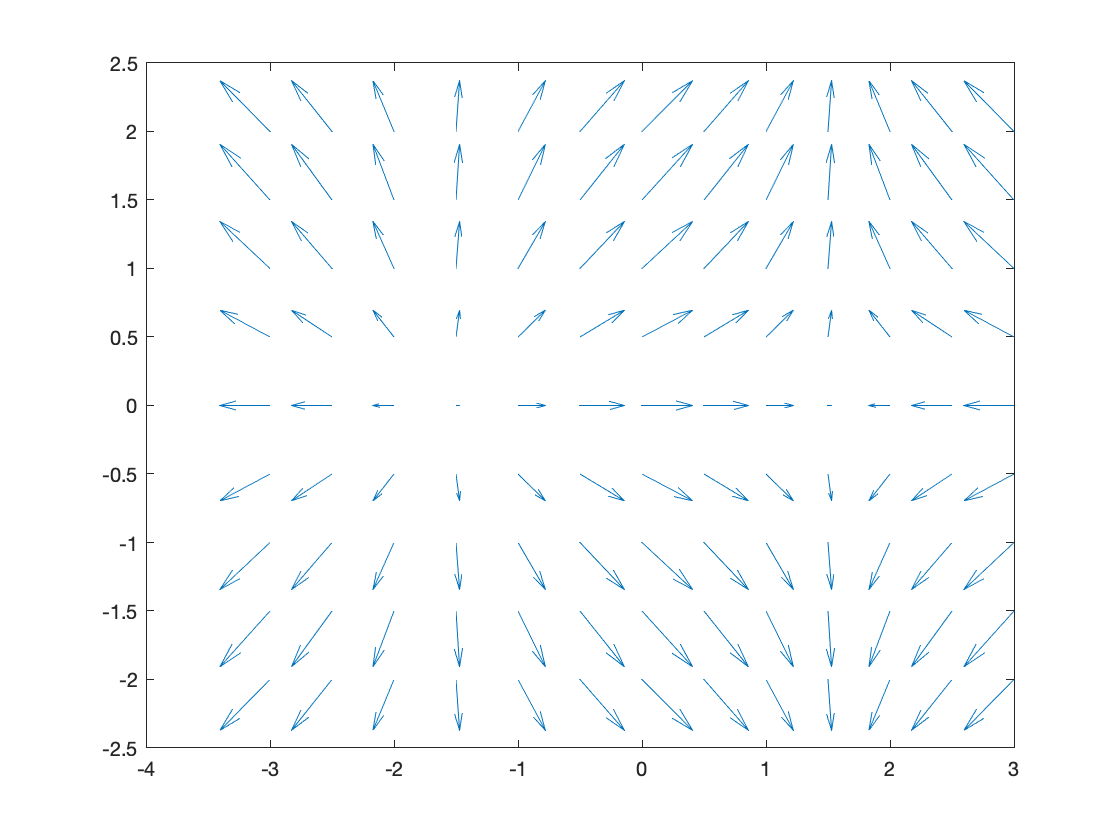

close all
% New variable C
CX = cos(X);
CY = sin(Y);
quiver(X,Y,CX,CY)

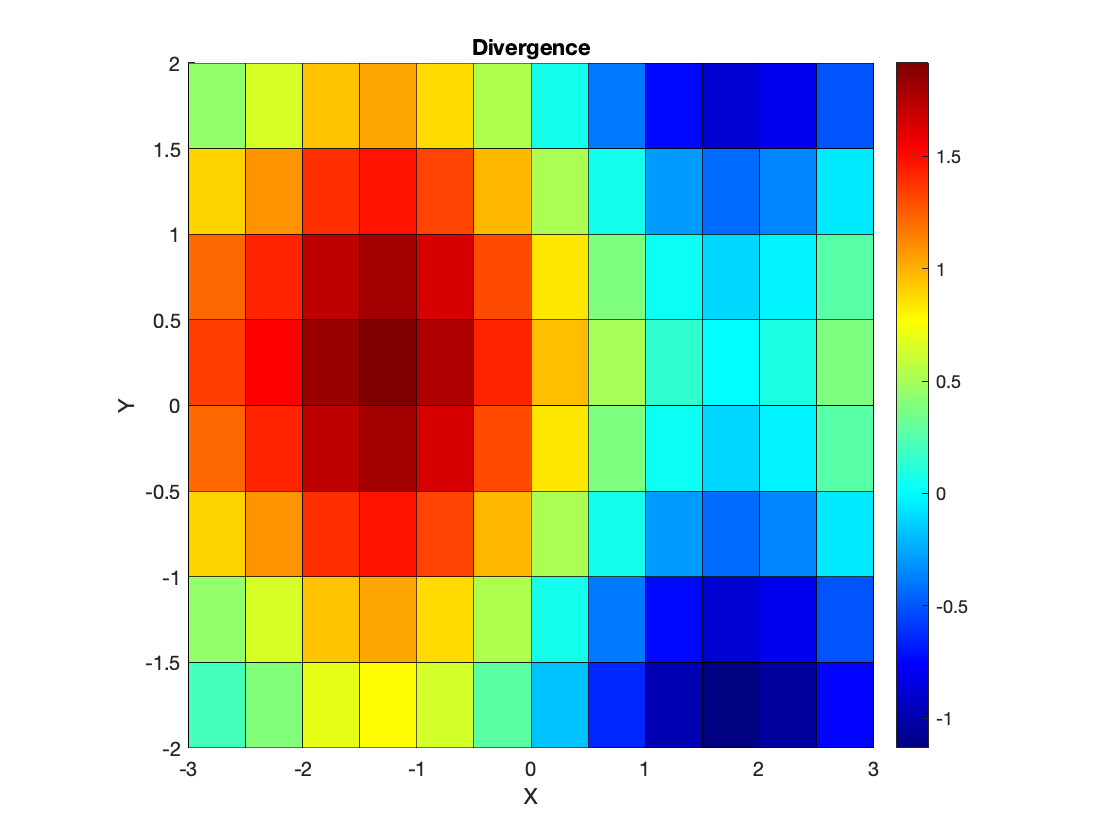


figure
% Calculate the divergence
DIV = divergence(X,Y,CX,CY);

% Plot the X component of the velocity
surface(X,Y,DIV)
axis square
title('Divergence')
xlabel('X')
ylabel('Y')
colorbar
colormap('jet')

**In physical systems**, the divergence may be thought of as the flux rate out of an infinitesimal region (+ for flux outward)

#### Integration

MATLAB offers the ability to perform **numerical integration** using the following functions (in order of increasing accuracy).

**Note**: these are **numerical** methods -- the integral can approximated from **evaluations of the original function**.

- Rectangle method:no built-in implementation in MATLAB

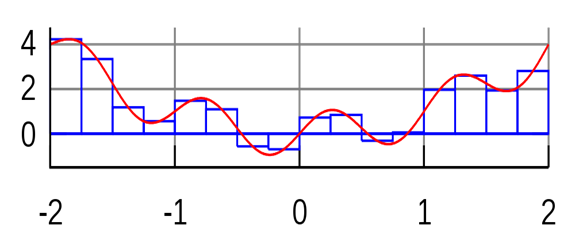

- Trapezoidal integration: accessed using the `trapz `function

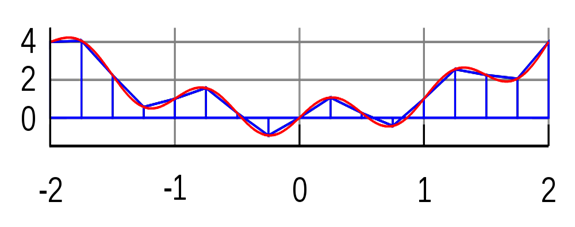

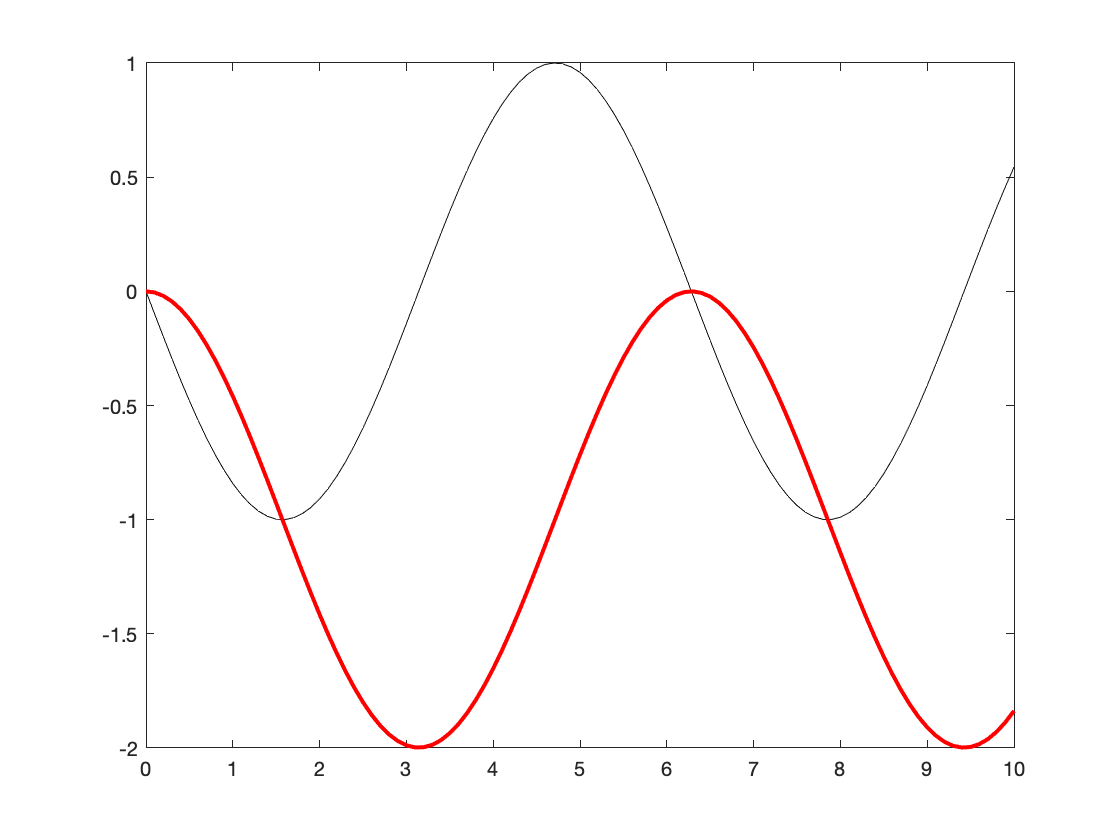

close all
% Define X and Y variables
x = 0:0.1:10;
y = -sin(x);
% Calculate definite integral over time
Y = zeros(size(y));
for k = 2:length(y)
    Y(k) = trapz(x(1:k),y(1:k));
end

% Plot the function and its *definite* integral
plot(x,y,'k-')
hold on
plot(x,Y,'r-','LineWidth',2)
hold off

- Quadrature integration: accessed using the `integral` function

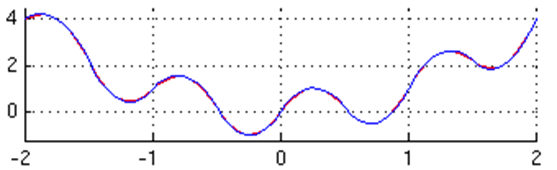

Numerical integration is most often approached in MATLAB using the `integral` function, which requires input as an anonymous function.

% Create function handle for function of interest
F = @(x) -sin(x)

F = function_handle with value:
    @(x)-sin(x)


% Calculate integral
q = integral(F,0,pi)

q = -2.0000

#### Engineering example: controllers

When describing (biological, chemical, mechanical, electrical) engineering systems, the engineer is often interested in how a given **output** results from a given **input**. 

*Examples of systems:*

- A medical device for regulating blood sugar levels

- A chemical reactor for producing acetylene

- A prosthetic hand

*Examples of inputs:*

- A voltage (related to amount of insulin to be injected into the patient).

- Calcium carbide reagent entry into a reactor

- An electrical signal applied to a mechanical actuator

*Examples of outputs:*

- A voltage from a sensor that is proportional to blood glucose levels

- Material and energy produced from chemical reaction.

- Change in position of prosthetic fingers

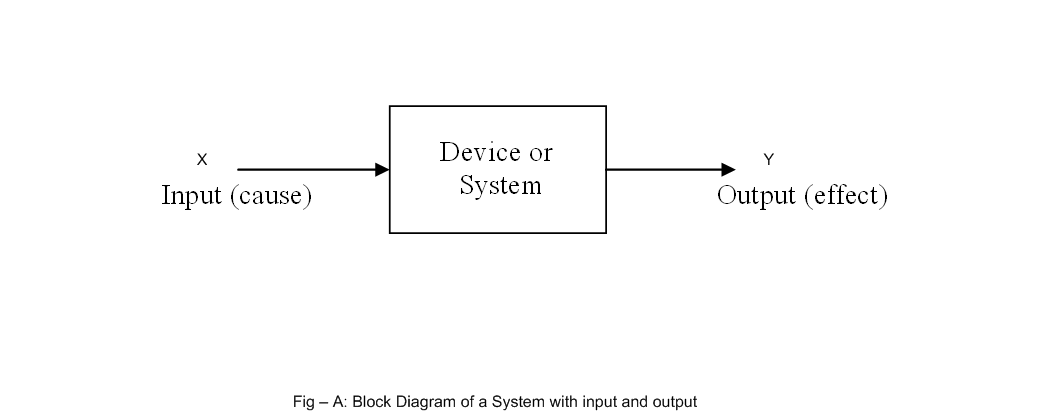

For example, consider the following code that represents some system. You can assume the following represents a device, in which it can be read (in real time) how an **output voltage** changes in response to the** input voltage.**

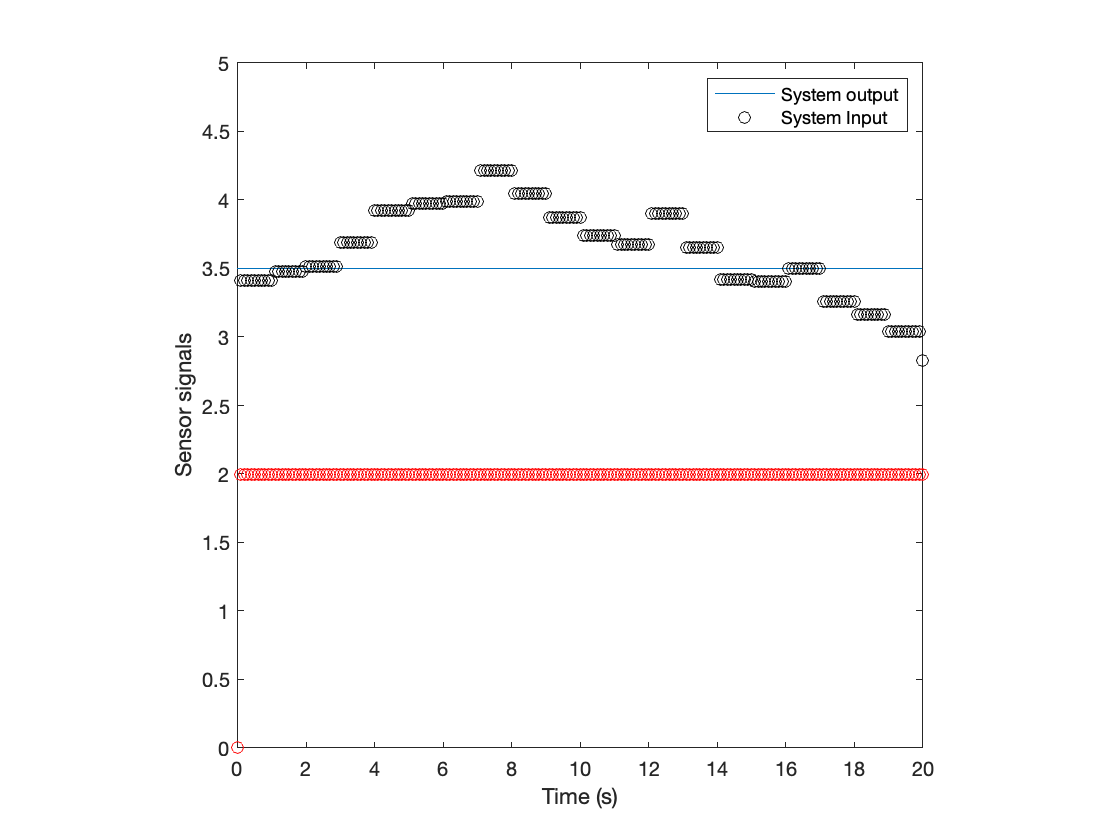

close all

% Create figure
h1 = figure;

plot([0,20],3.5*[1,1])
hold on
% Output "sensor" data
g_out = plot(0,0,'ko');
hold on
% Input "sensor" data
g_in = plot(0,0,'ro');
hold off

% Graphical parameters
xlim([0,20]);
ylim([0,5]);
axis square
ylabel('Sensor signals')
xlabel('Time (s)')
legend('System output','System Input','Location','NorthEast')

% Counter to store time
time = 0;
outError = 0;
   
% Plot in real time for 20 seconds
while time < 20

    % Pause for 100 ms
    pause(0.1);
    
    % Update time
    time = time + 0.1;
    
    % The following describes how the system responds to a given input
    % Assume the system drifts in some time dependent fashion
    outError = outError + (abs(mod(time,1)) < 0.1)*(rand - 0.5);
    % Function describing how output responds to input
    y = @(x) sqrt(x) + 2 + 0.5*outError;

    % Update vector to contain input information
    g_in.XData = [g_in.XData,time];
    g_in.YData = [g_in.YData,2];
    
    % Update vector to contain input information
    g_out.XData = [g_out.XData,time];
    g_out.YData = [g_out.YData,y(g_in.YData(end))];
    
end

Instead of simply observing how an output changes in reponse to a given input, engineers seek to **control** how the output varies in time. For example, a chemical process engineer wants to ensure that a chemical system is safely operating within the constraints providing by the equipment, process of interest, etc.

One way to implement this process control is to integrate a** feedback controller**. As shown in the following diagram, feedback control enables one to **adjust an input depending on how the output is changing** over time.

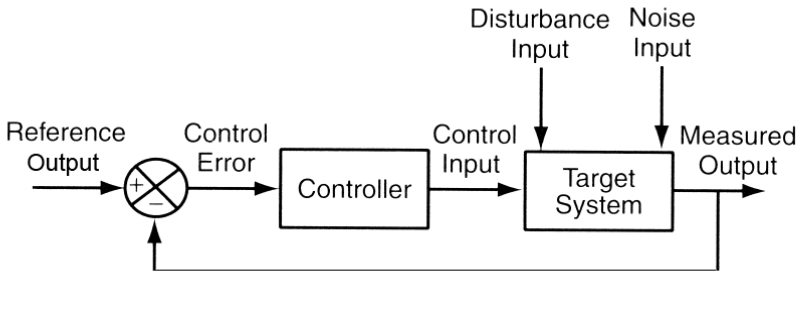

*Common types of controllers:*

- **Proportional**: the control input is proportional to the difference between the actual ouput and the set point.

- **Integral**: the conrol input is proporitional to the integrated difference between the actual output and the set point

- **Differential**: the control input is proportional to the differentiated difference between the actual output and the set point

Controllers can integrate multiple control strategies: **PI** controllers, **PID** controllers, etc. 

**Goal**. Create a **Proportional** and **PI** controller and observe the signal in real time.

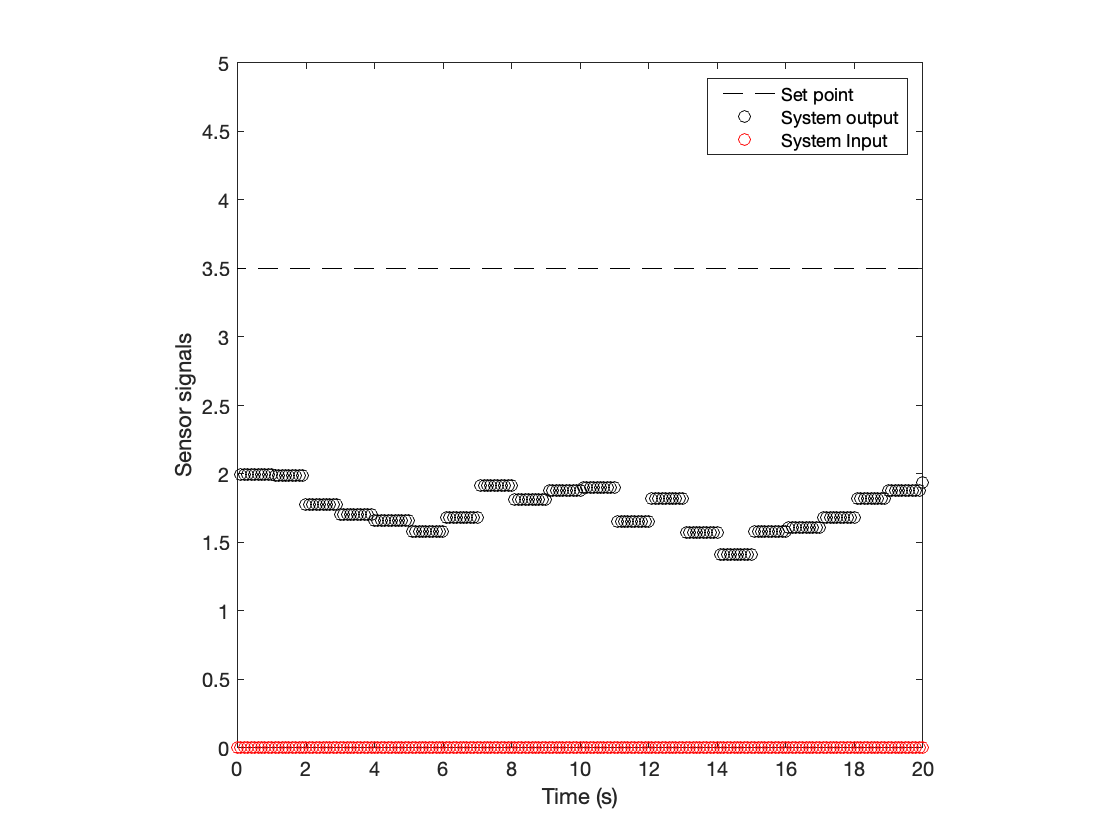

close all

% Create figure
h1 = figure;

% Determine our goal set point
ysp = 3.5;

plot([0,20],ysp*[1,1],'k--')
hold on
% Output "sensor" data
g_out = plot(0,0,'ko');
% Input "sensor" data
g_in = plot(0,0,'ro');
plot(xlim,ysp,'k-')
hold off

% Graphical parameters
xlim([0,20]);
ylim([0,5]);
axis square
ylabel('Sensor signals')
xlabel('Time (s)')
legend('Set point','System output','System Input','Location','NorthEast')

% Counter to store time
time = 0;
outError = 0;
   
% Declare a variable to represent the error from the set point
x_err = 0;

% Plot in real time for 20 seconds
while time < 20

    % Pause for 100 ms
    pause(0.1);
    
    % Update time
    time = time + 0.1;
    
    % The following describes how the system responds to a given input
    % Assume the system drifts in some time dependent fashion
    outError = outError + (abs(mod(time,1)) < 0.1)*(rand - 0.5);
    % Function describing how output responds to input
    y = @(x) sqrt(x) + 2 + 0.5*outError;

    % DEFINE CONTROLLER HERE
    if time > 0.1
        


    end
    
    
    % Update vector to contain input information
    g_in.XData = [g_in.XData,time];
    g_in.YData = [g_in.YData,max(0,x_err)];
    
    % Update vector to contain input information
    g_out.XData = [g_out.XData,time];
    g_out.YData = [g_out.YData,y(g_in.YData(end))];
    
end